%% file reads data from SAFT-VR MIE sheet for plotting and comparison with itterated values
newfolder = folder+"\Unknown SAFT";
SAFT = readtable("GR Hermanus (22796002).xlsx", "Sheet", "SAFT-VR MIE UNKNOWN");

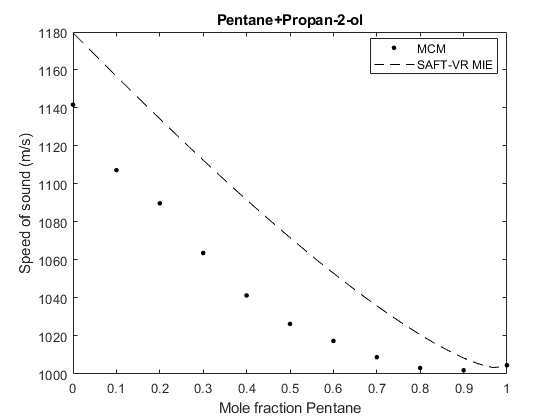

SAFT.Component1 = string(SAFT.Component1);
SAFT.Component2 = string(SAFT.Component2);
mixture = unique(SAFT.Component1 + "+" + SAFT.Component2);
mixture = mixture(2:end); %start at 2 cause 1 is just a plus sign?

for i = 1:numel(mixture)
    index1 = (Itterated.Component1 + "+" + Itterated.Component2) == mixture(i);
    index2 = (SAFT.Component1 + "+" + SAFT.Component2) == mixture(i);
    comp = Itterated.Composition1(index1); 
    
    if sum(index1) == 0
        index1 = (Itterated.Component2 + "+" + Itterated.Component1) == mixture(i);
        comp = 1-Itterated.Composition1(index1);
    end
    
    if sum(index1) ~= 0
        xx = "Mole fraction " + unique(SAFT.Component1(index2)); 
        subplot(1, 1, 1);
        plot(comp, Itterated.Speed_of_sound(index1), ".k", "MarkerSize", 10); hold on
        plot(SAFT.MolarComposition1(index2), SAFT.SpeedOfSound_m_s_(index2), "--k"); hold off
        title(mixture(i)); xlabel(xx);
        ylabel("Speed of sound (m/s)"); legend("MCM", "SAFT-VR MIE", "Location","best");
        
        filename = mixture(i)+".jpeg";
        f = getframe(gcf);
        %imwrite(f.cdata, fullfile(newfolder, filename));
    
        AAD_unknown.All(:,i) = abs(Itterated.Speed_of_sound(index1) - spline(SAFT.MolarComposition1(index2), SAFT.SpeedOfSound_m_s_(index2),comp))./...
            (spline(SAFT.MolarComposition1(index2), SAFT.SpeedOfSound_m_s_(index2),comp))*100;
        AAD_unknown.Average(:,i) = mean(AAD_unknown.All(:,i));
        AAD_unknown.Standard_Deviation(:,i) = std(AAD_unknown.All(:,i));
    else
        AAD_unknown.All(:,i) = zeros(11,1);
        AAD_unknown.Average(:,i) = 0;
        AAD_unknown.Standard_Deviation(:,i) = 0;
    end
end

%unknown_table = table(mixture, AAD_unknown.Average', AAD_unknown.Standard_Deviation');
%unknown_table.Properties.VariableNames = ["Mixture", "Average %AAD", "Standard Deviation %AAD"];
%writetable(unknown_table,"Unknown_SAFT.xlsx", "Sheet", "Secondary Alcohol")

%below code only for the entire datset uncomment if neccasary
%% file reads data from SAFT-VR MIE sheet for plotting and comparison with experimental values
% newfolder = folder+"\Known SAFT";
% SAFT = readtable("GR Hermanus (22796002).xlsx", "Sheet", "SAFT-VR MIE KNOWN");

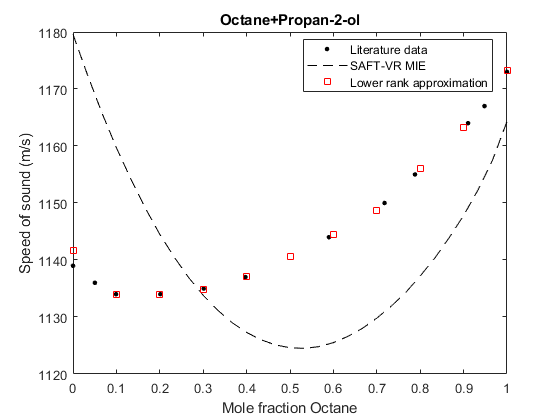

% SAFT.Component1 = string(SAFT.Component1);
% SAFT.Component2 = string(SAFT.Component2);
% mixture = unique(SAFT.Component1 + "+" + SAFT.Component2);
% 
% for i = 1:numel(mixture)
%     index1 = (Data.Component1 + "+" + Data.Component2) == mixture(i) & Data.Temperature_K_ == 298.15;
%     index2 = (SAFT.Component1 + "+" + SAFT.Component2) == mixture(i);
%     index3 = (Itterated_test.Component1(:,1) + "+" + Itterated_test.Component2(:,1)) == mixture(i);
%     comp1 = Data.MolarComposition1(index1); 
%     comp3 = Itterated_test.Composition1(index3,1);
%     
%     if sum(index1) == 0
%         index1 = (Data.Component2 + "+" + Data.Component1) == mixture(i) & Data.Temperature_K_ == 298.15;
%         comp1 = 1-Data.MolarComposition1(index1);
%     end
%     if sum(index3) == 0
%         index3 = (Itterated_test.Component2(:,1) + "+" + Itterated_test.Component1(:,1)) == mixture(i);
%         comp3 = Itterated_test.Composition1(index3,1);
%     end
%     
%     xx = "Mole fraction " + unique(SAFT.Component1(index2));
%     subplot(1, 1, 1);
%     plot(comp1, Data.SpeedOfSound_m_s_(index1), ".k", "MarkerSize", 10); hold on
%     plot(SAFT.MolarComposition1(index2), SAFT.SpeedOfSound_m_s_(index2), "--k"); 
%     plot(comp3, Itterated_test.Speed_of_sound(index3,1), 'sr'); hold off
%     title(mixture(i)); xlabel(xx);
%     ylabel("Speed of sound (m/s)"); legend("Literature data", "SAFT-VR MIE", "Lower rank approximation", "Location","best");
%     
%     filename = mixture(i)+".jpeg";
%     f = getframe(gcf);
%     imwrite(f.cdata, fullfile(newfolder, filename));
%     
%     AAD_known.All = abs(Data.SpeedOfSound_m_s_(index1) - spline(SAFT.MolarComposition1(index2), SAFT.SpeedOfSound_m_s_(index2),comp1))./...
%         (Data.SpeedOfSound_m_s_(index1))*100;
%     AAD_known.Average(:,i) = mean(nonzeros(AAD_known.All));
%     AAD_known.Standard_Deviation(:,i) = std(nonzeros(AAD_known.All));
% end

% known_table = table(mixture, AAD_known.Average', AAD_known.Standard_Deviation');
% known_table.Properties.VariableNames = ["Mixture", "Average %AAD", "Standard Deviation %AAD"];
% writetable(known_table,"Known_SAFT.xlsx")